# Baby Neural Network

doot doot doot doot doot do

Neurotechnology, Brains and Machines

Lily Jiang

September 28, 2023

This shows a very simple dataset and code to understand how a neural network works.

First, define your data. Neural networks in Matlab expect the dimensions to be features x examples (trials, people, etc).

x = [1.7691    1.8085    1.3774    1.1878    1.4386    1.2363    1.8217    1.1834    1.7689    1.3276    1.0861    1.8878    0.7428    1.7904  0.9423    1.2703    1.3309    1.2413    0.5445    0.8477; ...
    0.3968    0.7551    0.2160    0.3592    0.8335    0.3947    0.4299    0.7040    0.1673    0.6713    0.2621    0.3912    0.4424    0.9493  0.0196    0.1971    0.4243    0.5201    0.7549    0.1500]

x =     1.7691    1.8085    1.3774    1.1878    1.4386    1.2363    1.8217    1.1834    1.7689    1.3276    1.0861    1.8878    0.7428    1.7904    0.9423    1.2703    1.3309    1.2413    0.5445    0.8477
    0.3968    0.7551    0.2160    0.3592    0.8335    0.3947    0.4299    0.7040    0.1673    0.6713    0.2621    0.3912    0.4424    0.9493    0.0196    0.1971    0.4243    0.5201    0.7549    0.1500


t = [1	1	1	0	1	0	1	0	1	1	0	1	0	1	0	1	0	0	0	0];

Let's plot our data to understand them.

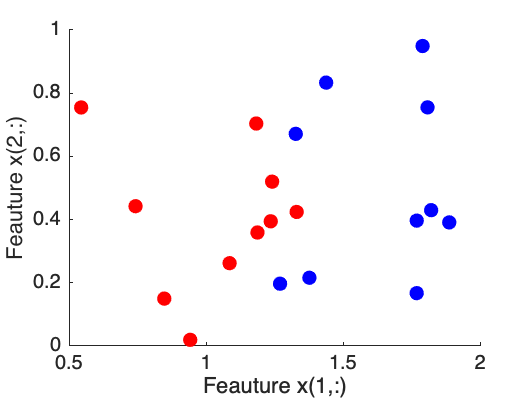

figure;
hold on;
plot(x(1,t==0),x(2,t==0),'r.','MarkerSize',20);
plot(x(1,t==1),x(2,t==1),'b.','MarkerSize',20);
xlabel('Feauture x(1,:)');
ylabel('Feauture x(2,:)');
hold off;

Configure our (shallow) neural network

This network has:

- one input layer of size = 2, aka, two vectors in, the two rows of x (each is a feature)

- two hidden layers

- one output layer

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Levenberg-Marquardt backpropagation.

% Create a Fitting Network
hiddenLayerSize = [3];
%net = perceptron;
net = patternnet(hiddenLayerSize,trainFcn);
net = configure(net,x,t);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

### Summarize current network (before training)

Now, we can explore the network to see what it looks like to start.

net

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 13
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

% view(net) % pop up a visual

To find the sizes of things, we look in the inputs and layers.

net.inputs{1}.size  % number of input features

ans = 2

net.layers{1}.size

ans = 3

net.layers{2}.size  % If it is a 2-layer network, this is same as output.

ans = 1

net.outputs{net.numLayers}.size  % For us, this is the same as the layers

ans = 1

Explore initialized model (no learning yet)

We start with randomly initialized weights and values. 

#### Input normalizing

First, we do a little normalization of our data using ((x - xoffset).*gain) + ymin

try 
    input_xoffset = net.Inputs{1}.processSettings{2}.xoffset
    input_gain = net.Inputs{1}.processSettings{2}.gain
    input_ymin = net.Inputs{1}.processSettings{2}.ymin
catch
    input_xoffset = net.Inputs{1}.processSettings{1}.xoffset
    input_gain = net.Inputs{1}.processSettings{1}.gain
    input_ymin = net.Inputs{1}.processSettings{1}.ymin
end

input_xoffset =     0.5445
    0.0196


input_gain =     1.4889
    2.1512


input_ymin = -1

#### Input layer to hidden layer

input2hidden_weights = net.IW{1} % Input weights (from input layer to hidden layer)

input2hidden_weights =     2.3978   -0.3615
   -1.9582   -1.4302
    0.9992   -2.2094


input2hidden_weights_beforetrain = input2hidden_weights; % Use this later
input2hidden_biases = net.b{1}  % Bias on the inputs (from input layer to hidden layer)

input2hidden_biases =    -2.4249
         0
    2.4249


This is the "transfer function" or the "activation function"

input2hidden_activationfunction = net.layers{1}.transferFcn

input2hidden_activationfunction = 'tansig'

#### Hidden layer to output layer

hidden2output_weights = net.LW{2,1}  % Weights from hidden layer to output layer

hidden2output_weights =     1.5929   -1.5999   -1.6562


hidden2output_weights_beforetrain = hidden2output_weights; %Use this later
hidden2output_layer_biases = net.b{2} % Bias on the hidden layer to output layer

hidden2output_layer_biases = 0

hidden2output_activationfunction = net.layers{2}.transferFcn

hidden2output_activationfunction = 'logsig'

### Calculate forward pass (before training)

1) Start with a single example of x.

single_x = x(:,1)  % First example

single_x =     1.7691
    0.3968


2) Normalize the inputs  ((x - xoffset).*gain) + ymin

interim_x = ((single_x - input_xoffset).*input_gain) + input_ymin

interim_x =     0.8233
   -0.1886


3) 

z1 = (input2hidden_weights * interim_x ) + input2hidden_biases

z1 =    -0.3827
   -1.3424
    3.6641


input2hidden_activationfunction

input2hidden_activationfunction = 'tansig'

a1 = tansig(z1)

a1 =    -0.3650
   -0.8723
    0.9987


second layer

z2 = (hidden2output_weights * a1) + hidden2output_layer_biases

z2 = -0.8400

hidden2output_activationfunction

hidden2output_activationfunction = 'logsig'

a2 = logsig(z2)

a2 = 0.3015

Now, put that same datapoint through the neural network to get an output

single_y = net(single_x)

single_y = 0.3015

Reality

t(1)

ans = 1

## Run all data through and plot (before training)

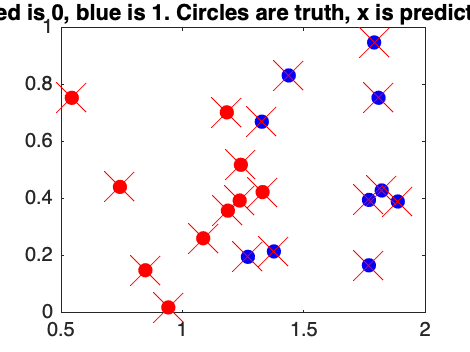

output_y = net(x);
output_binary = double(output_y >= .5);

figure; 
plot(x(1,t==0),x(2,t==0),'r.','MarkerSize',20); hold on; plot(x(1,t==1),x(2,t==1),'b.','MarkerSize',20); 
plot(x(1,output_binary==0),x(2,output_binary==0),'rx','MarkerSize',20); hold on; plot(x(1,output_binary==1),x(2,output_binary==1),'bx','MarkerSize',20);
hold off;
title('Red is 0, blue is 1. Circles are truth, x is prediction');

## Train the network

When you run this, a window should pop up. You can see various plots by clicking the buttons to see how the training went.

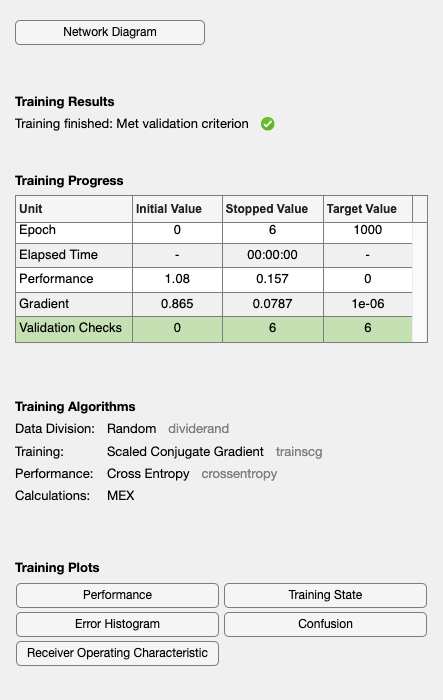

% Train the Network
[net,tr] = train(net,x,t);

## Run all data through and plot (AFTER training)

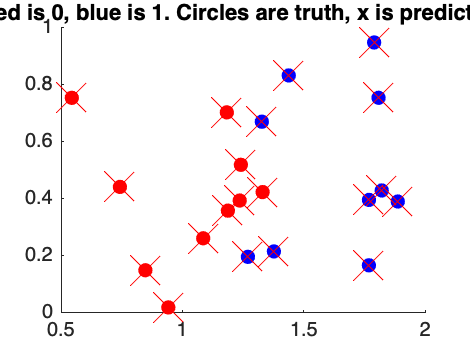

output_y = net(x);
output_binary = double(output_y >= .5);

figure;
hold on;
plot(x(1,t==0),x(2,t==0),'r.','MarkerSize',20);
plot(x(1,t==1),x(2,t==1),'b.','MarkerSize',20); 
plot(x(1,output_binary==0),x(2,output_binary==0),'rx','MarkerSize',20);
plot(x(1,output_binary==1),x(2,output_binary==1),'bx','MarkerSize',20);
hold off;
title('Red is 0, blue is 1. Circles are truth, x is prediction');

### Summarize current network (after training)

#### Input normalizing

First, we do a little normalization of our data using ((x - xoffset).*gain) + ymin

try 
    input_xoffset = net.Inputs{1}.processSettings{2}.xoffset
    input_gain = net.Inputs{1}.processSettings{2}.gain
    input_ymin = net.Inputs{1}.processSettings{2}.ymin
catch
    input_xoffset = net.Inputs{1}.processSettings{1}.xoffset
    input_gain = net.Inputs{1}.processSettings{1}.gain
    input_ymin = net.Inputs{1}.processSettings{1}.ymin
end

input_xoffset =     0.5445
    0.0196


input_gain =     1.4889
    2.1512


input_ymin = -1

#### Input layer to hidden layer

input2hidden_weights = net.IW{1} % Input weights (from input layer to hidden layer)

input2hidden_weights =     2.3978   -0.3615
   -1.9582   -1.4302
    0.9992   -2.2094


input2hidden_biases = net.b{1}  % Bias on the inputs (from input layer to hidden layer)

input2hidden_biases =    -2.4249
         0
    2.4249


This is the "transfer function" or the "activation function"

input2hidden_activationfunction = net.layers{1}.transferFcn

input2hidden_activationfunction = 'tansig'

#### Hidden layer to output layer

hidden2output_weights = net.LW{2,1}  % Weights from hidden layer to output layer

hidden2output_weights =     1.5929   -1.5999   -1.6562


hidden2output_layer_biases = net.b{2} % Bias on the hidden layer to output layer

hidden2output_layer_biases = 0

hidden2output_activationfunction = net.layers{2}.transferFcn

hidden2output_activationfunction = 'logsig'

## Calculate the forward pass for a single value

#### Exercise: For the first example of x, manually calcuate the forward pass (the network output) after training. 

You have updated the necessary variables in the section above. Now implement each step (see the forward pass code earlier for an example). 

first_x = x(:,1)

first_x =     1.7691
    0.3968



% Normalize inputs
interim_x = ((first_x - input_xoffset).*input_gain) + input_ymin

interim_x =     0.8233
   -0.1886



% Layer 1
z1 = (input2hidden_weights * interim_x ) + input2hidden_biases

z1 =    -0.3827
   -1.3424
    3.6641


input2hidden_activationfunction

input2hidden_activationfunction = 'tansig'

a1 = tansig(z1)

a1 =    -0.3650
   -0.8723
    0.9987



% Layer 2
z2 = (hidden2output_weights * a1) + hidden2output_layer_biases

z2 = -0.8400

hidden2output_activationfunction

hidden2output_activationfunction = 'logsig'

a2 = logsig(z2)

a2 = 0.3015


% Get output from neural network
single_y = net(single_x)

single_y = 0.3015

t(1)  % reality

ans = 1

## Compare weights before and after training

#### Exercise: Make plots showing the weights for the input to hidden layer and the hidden to output layer. Do this for before and after training.

Hint: imagesc and subplots is a nice way to visualize this.

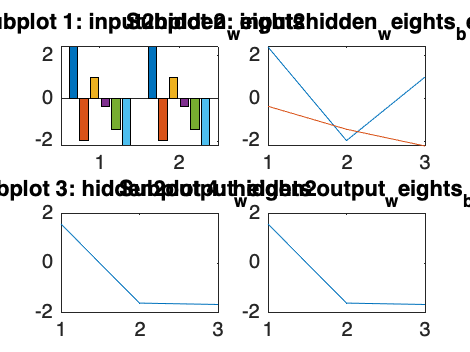

subplot(2,1,1);
bar([reshape(input2hidden_weights, 1, []); reshape(input2hidden_weights_beforetrain, 1, [])]);
title('Subplot 1: input weights');

subplot(2,1,2);
bar([reshape(hidden2output_weights, 1, []); reshape(hidden2output_weights_beforetrain, 1, [])]);
title('Subplot 2: output weights');